# bisectionAlgorithm - Analisi di robustezza, accuratezza e prestazioni

In questo documento sono mostrati i test relativi all'algoritmo di bisezione implementato. L'accuratezza e le prestazioni dell'algoritmo sono state misurate e un confrontate con la funzione `fzero` offerta dal Matlab. 

# Test di accuratezza

Il parametro che sarà preso come misura di riferimento è il risultato forniro dalla funzione `fzero `offerta dal Matlab; in particolare, si utilizzerà la funzione `accuracy_bisectionAlgorithm()`, allegata alla documentazione, che confronta i risultati ottenuti con `bisectionAlgorithm` e `fzero` fornendone l'errore relativo.

f = @(x)(2-exp(-x)-sqrt(x));
x0 = [0 4];
TOL=[1e-1 1e-2 1e-4 1e-6 1e-8 1e-10 1e-12 1e-14 eps];

for i=1:length(TOL)
    accuracy_bisectionAlgorithm(f,x0,TOL(i))
end

ans = 0.0625

ans = 0.0035

ans = 7.4462e-06

ans = 6.3621e-07

ans = 6.0506e-09

ans = 1.5855e-11

ans = 8.4058e-13

ans = 2.2651e-16

ans = 2.2651e-16

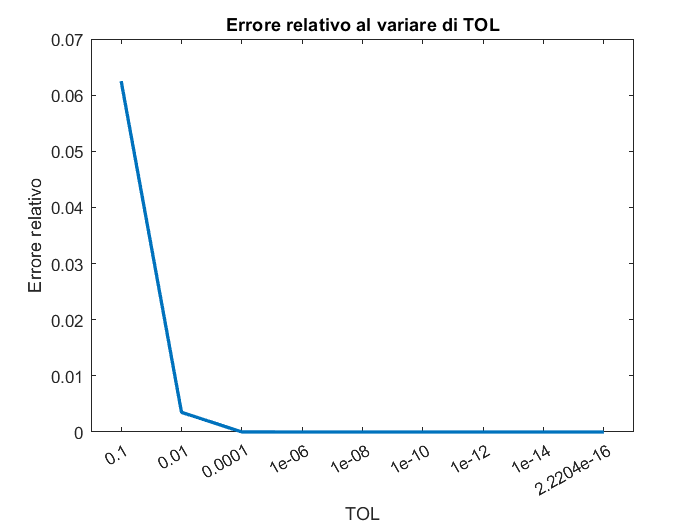


plotAccuracy_bisectionAlgorithm(f,x0,TOL);

A crescere della tolleranza l'errore relativo tende asintoticamete a zero e quidi  si riesce ad ottenere un risulato accuarato anche con `bisectionAlgorithm.`

# Prestazioni

Come metrica per valutare le prestazioni dell'algoritmo sviluppato si è utilizzato il numero di iterazioni, In particolare, si sono confrontati il numero di iterazioni necessarie per calcolare uno zero con `fzero` e con `bisectionAlgorithm `al variare della tolleranza`.` È evidente che, pur avendo raggiunto un buon grado di accuratezza, l'algoritmo implementato è molto meno efficiente della soluzione offerta da Matlab, la differenza diventa tanto più evidente quanto più aumenta il grado di risoluzione richiesta alla soluzione.

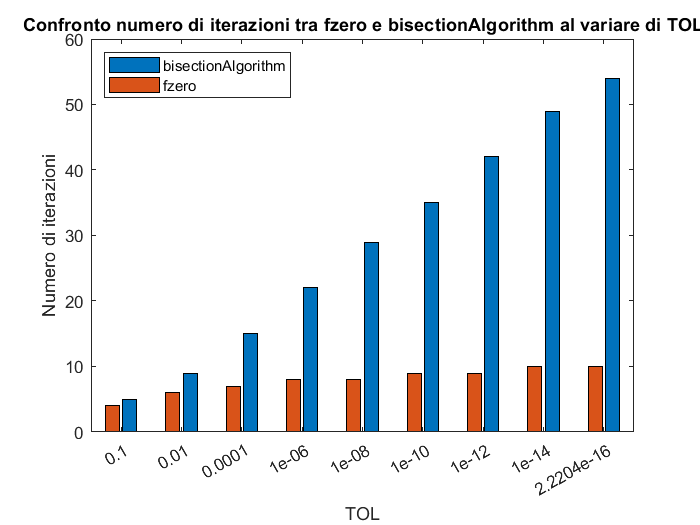

fun = @(x)(x.^2-2);
range = [0 4];
TOL=[1e-1 1e-2 1e-4 1e-6 1e-8 1e-10 1e-12 1e-14 eps];

plotPerfomance(fun,range,TOL);

# Test di robustezza

Per la progettazione dei casi di test è stato utilizzato il metodo di *Category-partition testing *[1]. In particolare, sono state individuate delle categorie in base ai parametri (di ingresso e uscita) modificabili dall'utente, in base all'ipotesi del teorema di esistenza degli zeri (su cui si basa l'algoritmo) e sul numero di parametri di output; i valori sono stati scelti in base alle condizioni di errore/warning in cui ci si può venire a trovare.

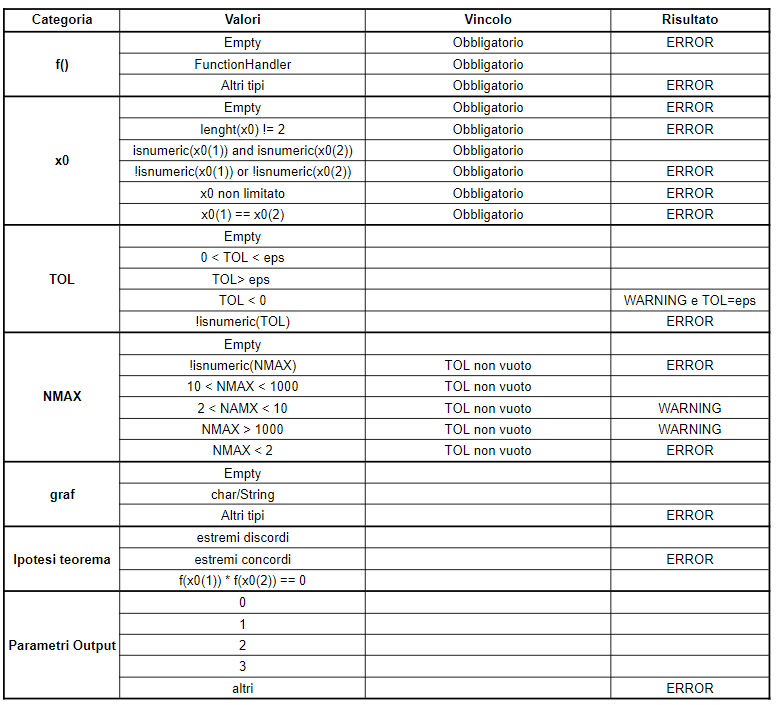

Per l'implementazione dei casi di test è stato utilizzato il framework di MatLab per il testing di unità [2]*; *questa scelta ha permesso di automatizzare completamente l'esecuzione dei test: infatti, è possibile lanciare la simulazione con l'istruzione

Running testSuite
..

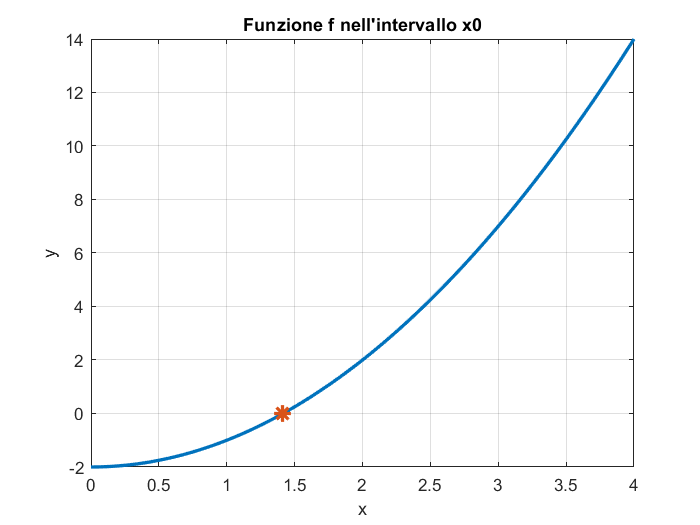

........ .......... ..
Done testSuite
__________



results =   1×22 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   22 Passed, 0 Failed, 0 Incomplete.
   0.39349 seconds testing time.


results = runtests('testSuite.m')

Il sistema esegue in automatico i test, riportando in `results `un sommario .

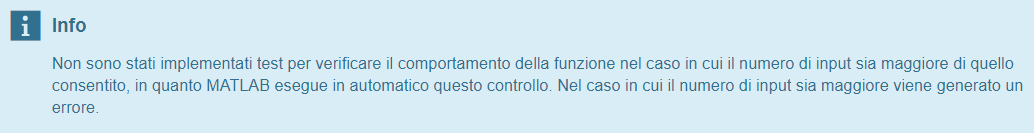

Tutti i test che prevedevano una funzione e/o un intervallo in ingresso sono stati eseguiti con i seguenti parametri di ingressi :  

f = @(x)(2-exp(-x)-sqrt(x));
x0 = [0 4];

Di seguito viene descritta l'implementazione di alcuni casi di test a titolo esemplificativo.

## Caso di test 1                                                                                                                         

La configurazione dei parametri è:

- `f     `: **valido**

- `x0    `: **valido**

- `TOL   `: **vuoto**

- `NMAX  `: **vuoto**

- graf     : **vuoto** 

- `ipotesi del teorema `: **verificate**

- `parametri di output `: `1`

function testFunctionCase1(testCase)

    [fun,range] = getGlobalParameter;
    
    actSolution= bisectionAlgorithm(fun,range);
    expSolution= fzero(fun,range);
    
    abs_error= abs(actSolution-expSolution);
    if abs_error<= eps*max(actSolution,expSolution)
        % passed
        verifyReturnsTrue(testCase,@true);
    else
        % not passed
        verifyReturnsTrue(testCase,@false);
    end
end

Viene calcolato lo zero di `f `sia con `bisectionAlgorithm sia `con `fzero; `confrontando l'errore assoluto con l'epsilon associato al max dei risultati si può decidere se la risoluzione del calcolo è sufficiente.

## Caso di test 20                                                                                                                         

La configurazione dei parametri è:

- `f     `: **valido**

- `x0    `: **valido**

- `TOL   `: **valido**

- `NMAX  `:** 0 < NMAX < 10**

- graf     : **vuoto**

- `ipotesi del teorema `: **verificate**

- `parametri di output `: `1`

NOTA: lo zero si trova nell'estremo dell'intervallo

function testFunctionCase20(testCase)    
    fun = @(x)(x.^2 - 1);
    range = [0 1]; 
    [~,fx]= bisectionAlgorithm(fun,range);
    verifyEqual(testCase,fx.niter,0);
end

In questo caso non sono stati usati i parametri `"globali"` usati per i test precedenti. L'obiettivo del test è verificare che l'algoritmo trova subito lo zero se questo è in corrispondenza di uno degli estremi dell'intevallo passato in ingresso; tale controllo viene effettuato valutanto il numero di iterazioni effettuate controllando il campo `niter` del secondo parametro di uscita `fx.`

## Riferimenti                                                                                                                  

[1] *Robert D. Cameron, 2013, *[http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html](http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html)

[2] Matlab Documentation, [https://it.mathworks.com/help/matlab/function-based-unit-tests.html](https://it.mathworks.com/help/matlab/function-based-unit-tests.html)

## Autore                                                                                                                   

Gabriele Previtera